# Generate our Bell Parameter off the correlations:

## Lists:

phi = 0:2*pi/99:2*pi;
E_list = 0.*phi;

## Parameters:

$\lambda$ = L - mode occupancy.  

$\phi$ - phase of interferometer.  

$T_{max}$ - maximum number of generated particle

cycles = C - number of simulated tests used to perform correlation.

QE = R - retention rate / quantum efficiency.

dark_rate = D - fraction of tests which return a non-experimental count.

$\sigma$ = B - decay width of gaussian blur in detection uncertainty.

R - radius of $He_4$ halos.

phys - Quantum ('Q') or Classical ('C') physics to be used.

$Y_{\text{bias}}$ - with a classical beam splitter, the R.H.S. bias towards Y (up)

$X_{\text{bias}}$ -         "             "                      , the L.H.S. bias towards X (up)

lambda = 0.1;
% phi =   ;
Tmax = 10;
cycles = 2E4;
QE = 50;
dark_rate = 0;
sigma = 0.05;
R = 1;
phys = 'Q';

## Evaluation for each phase:

percent = 1

percent = 2

percent = 3

percent = 4

percent = 5

percent = 6

percent = 7

percent = 8

percent = 9

percent = 10

percent = 11

percent = 12

percent = 13

percent = 14

percent = 15

percent = 16

percent = 17

percent = 18

percent = 19

percent = 20

percent = 21

percent = 22

percent = 23

percent = 24

percent = 25

percent = 26

percent = 27

percent = 28

percent = 29

percent = 30

percent = 31

percent = 32

percent = 33

percent = 34

percent = 35

percent = 36

percent = 37

percent = 38

percent = 39

percent = 40

percent = 41

percent = 42

percent = 43

percent = 44

percent = 45

percent = 46

percent = 47

percent = 48

percent = 49

percent = 50

percent = 51

percent = 52

percent = 53

percent = 54

percent = 55

percent = 56

percent = 57

percent = 58

percent = 59

percent = 60

percent = 61

percent = 62

percent = 63

percent = 64

percent = 65

percent = 66

percent = 67

percent = 68

percent = 69

percent = 70

percent = 71

percent = 72

percent = 73

percent = 74

percent = 75

percent = 76

percent = 77

percent = 78

percent = 79

percent = 80

percent = 81

percent = 82

percent = 83

percent = 84

percent = 85

percent = 86

percent = 87

percent = 88

percent = 89

percent = 90

percent = 91

percent = 92

percent = 93

percent = 94

percent = 95

percent = 96

percent = 97

percent = 98

percent = 99

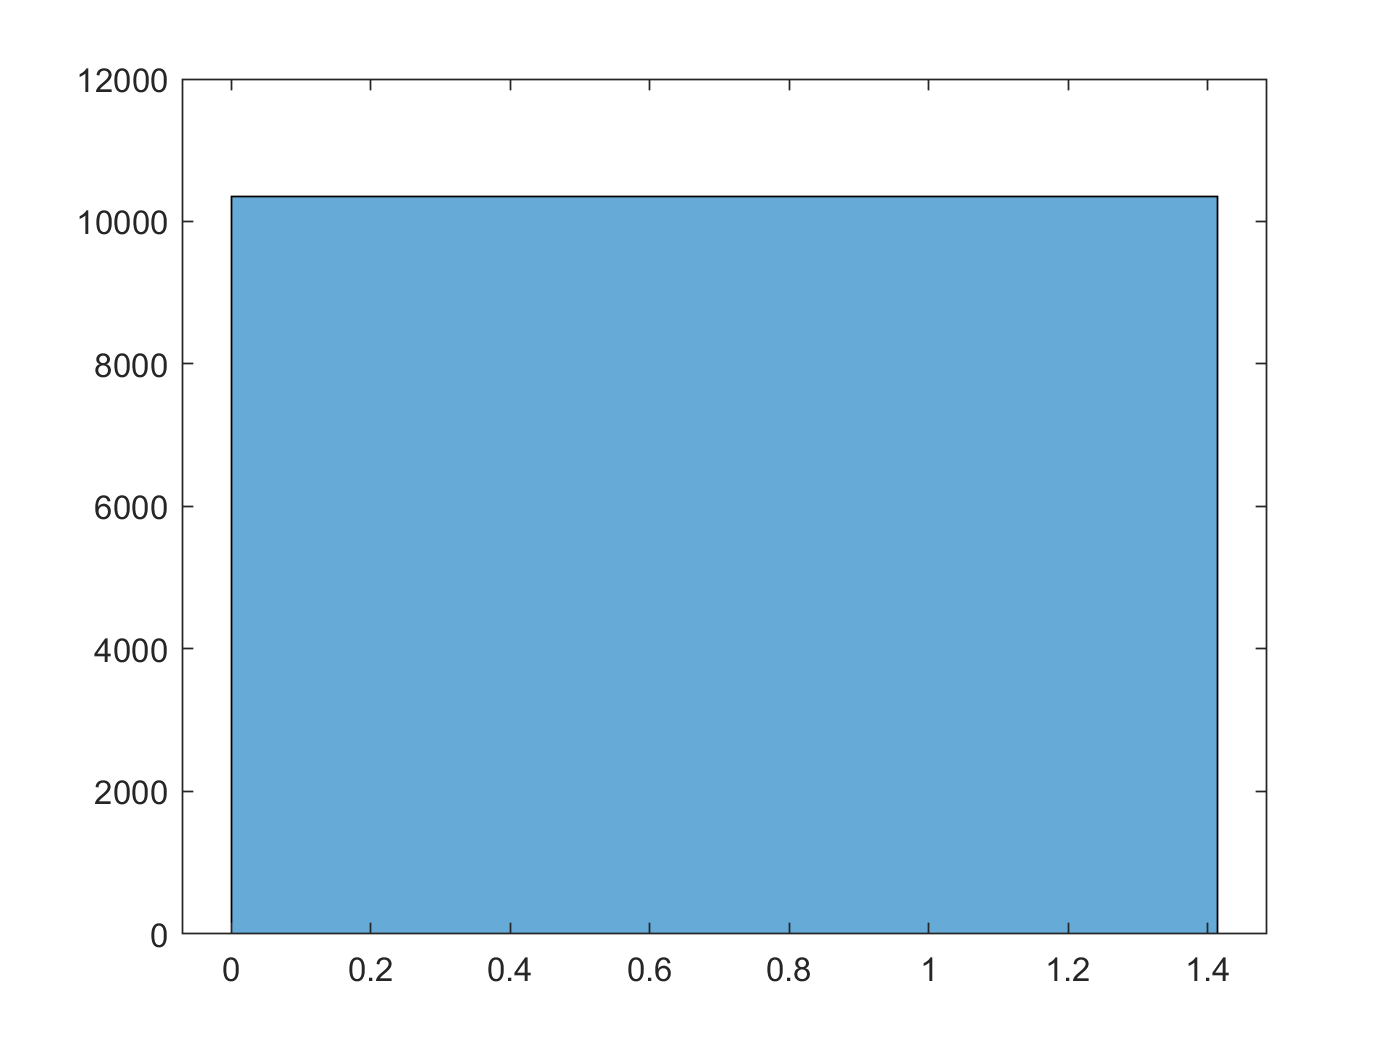

percent = 100

for p = 1:length(phi)
    [g_YX,g_WZ,g_YZ,g_XW] = correlators3(lambda,phi(p),Tmax,cycles,QE,dark_rate,sigma,sqrt(2),phys,0.5,0.5);
    E_list(p) = (g_YX+g_WZ-g_YZ-g_XW)/(g_YX+g_WZ+g_YZ+g_XW);
    percent = 100*p/length(phi)
end

## Generate Plot / Image:

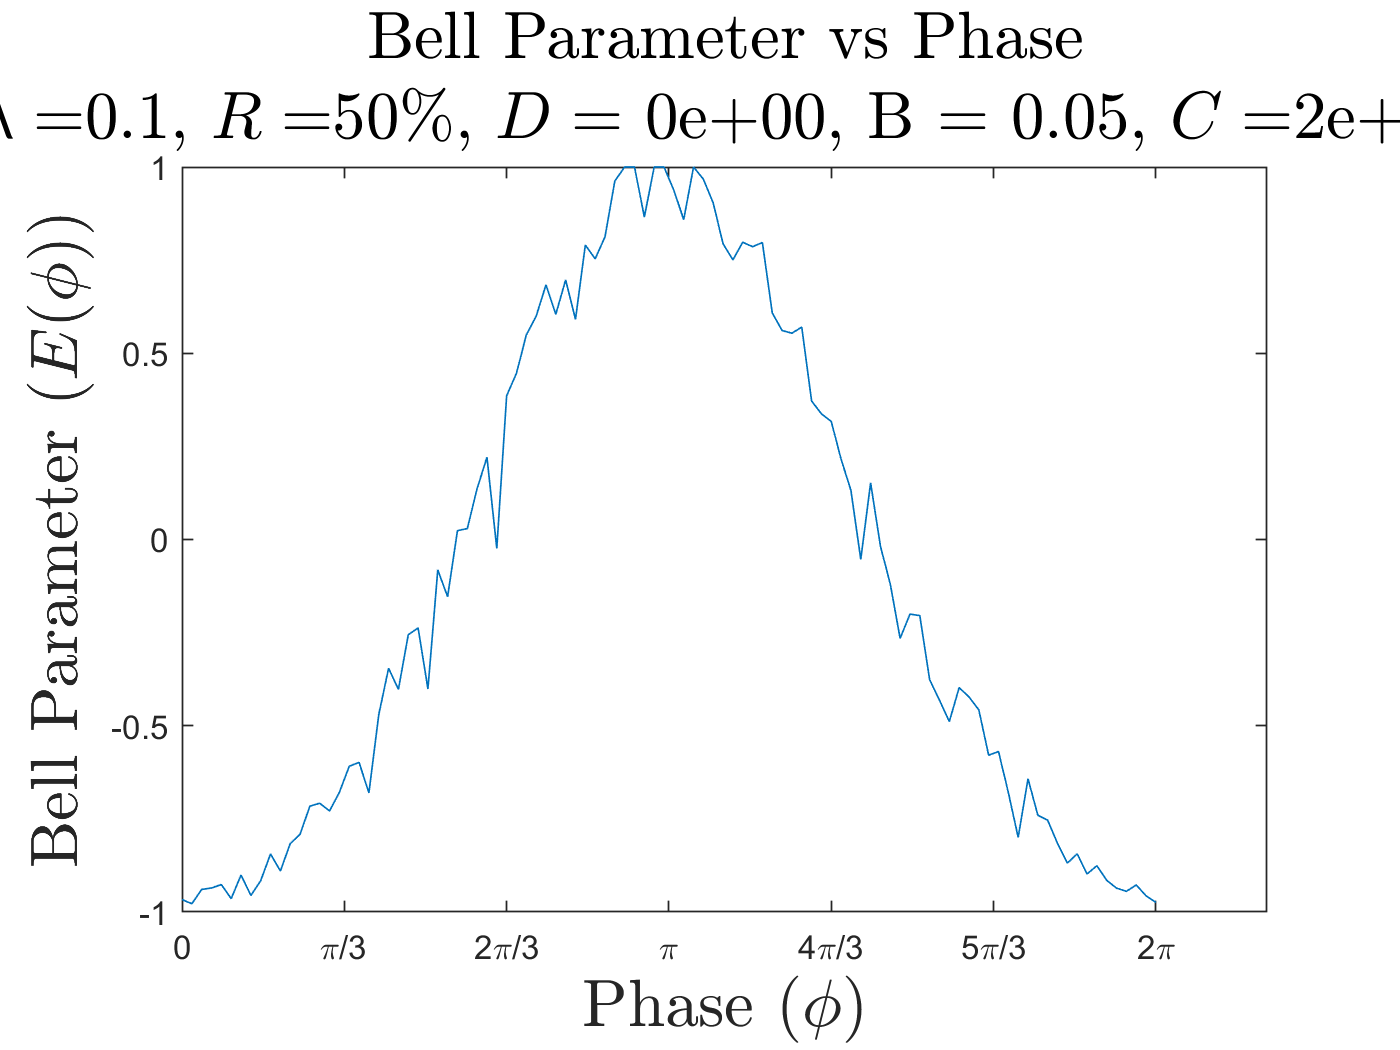

plot(phi,E_list)
xticks([0,pi/3,2*pi/3,pi,4*pi/3,5*pi/3,2*pi])
xticklabels(["0","\pi/3","2\pi/3","\pi","4\pi/3","5\pi/3","2\pi"])
xlabel("Phase ($\phi$)","Interpreter",'latex','FontSize',20)
ylabel("Bell Parameter ($E(\phi)$)","Interpreter","latex",'FontSize',20)
title({"Bell Parameter vs Phase","$\lambda = $" + string(lambda) + ", $R =$" + string(QE)+"\%, $D = $" + " "+num2str(dark_rate, '%.0e')+", B = "+string(sigma)+", $C = $"+num2str(cycles,'%.0e')},"Interpreter","latex",'FontSize',20)

## Write to File:

A = [phi; E_list];
name = erase('R'+string(QE)+'_D'+num2str(dark_rate,'%.0e')+'_B'+string(sigma)+'_C'+num2str(cycles,'%.0e')+'_L'+string(lambda),'.');
data = fopen(name+'.txt','w');
fprintf(data,'%6s %12s\n','\phi','E(\phi)');
fprintf(data,'%6.4f %12.8f\n',A);
fclose(data);